% 2022.07.19 - Gain test visualization

% clear all
gain_test_results_default(1) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-13-10-58.mat'); % unevenground_0_1_v2_7, k_bar_ba = 0
gain_test_results_default(2) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-15-16-59.mat'); % unevenground_0_1_v2_7, k_bar_ba = 0
gain_test_results_default(3) = load('gain_test_results\5LinkWalkingOpenOCL2022-10-13-18-05.mat'); % unevenground_0_1_v2_13, k_bar_ba = 0
gain_test_results_default(4) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-20-21-54.mat'); % unevenground_0_1_v2_14, k_bar_ba = 0
gain_test_results_default(5) = load('gain_test_results\5LinkWalkingOpenOCL2022-10-16-10-19.mat'); % unevenground_0_1_v2_15, k_bar_ba = 0

% check if all gain_test_results_default is defult model
for i = 1:length(gain_test_results_default)
    assert(gain_test_results_default(i).gain_test_result.params.k_ba == 0)
end

gain_test_results_BA(1) = load('gain_test_results\5LinkWalkingOpenOCL2022-09-27-22-47.mat'); % unevenground_0_1_v2_7, k_bar_ba != 0
gain_test_results_BA(2) = load('gain_test_results\5LinkWalkingOpenOCL2022-10-13-18-37.mat'); % unevenground_0_1_v2_12, k_bar_ba != 0
gain_test_results_BA(3) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-20-12-37.mat'); % unevenground_0_1_v2_13, k_bar_ba != 0
gain_test_results_BA(4) = load('gain_test_results\5LinkWalkingOpenOCL2022-10-16-10-18.mat'); % unevenground_0_1_v2_14, k_bar_ba != 0
gain_test_results_BA(5) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-28-13-37.mat'); % unevenground_0_1_v2_15, k_bar_ba != 0

% check if all gain_test_results_default is defult model
for i = 1:length(gain_test_results_BA)
    assert(gain_test_results_BA(i).gain_test_result.params.k_ba ~= 0)
end

% default
def_x = gain_test_results_default(2).gain_test_result.gains_KD;
def_y = gain_test_results_default(2).gain_test_result.gains_KP;
def_PASS = gain_test_results_default(2).gain_test_result.PASS;

size_def = size(def_PASS)

size_def =    100    26


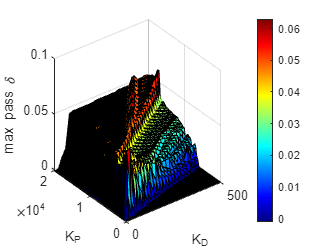


figure()
surf(def_x, def_y(1:size_def(1)), def_PASS)
colormap jet
colorbar

% caxis([-0.001 max(max(gain_test_results_BA.gain_test_result.PASS))])

xlabel('K_D')
ylabel('K_P')
zlabel('max pass \delta')
zlim([-0.001,0.1])
xlim([0,500])

% BA
BA_x = gain_test_results_BA(5).gain_test_result.gains_KD;
BA_y = gain_test_results_BA(5).gain_test_result.gains_KP;
BA_PASS = gain_test_results_BA(5).gain_test_result.PASS;

size_BA = size(BA_PASS)

size_BA =    100    26


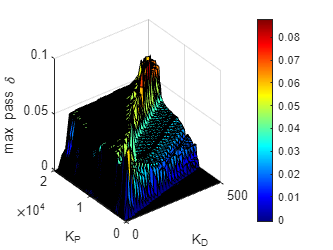


figure()
surf(BA_x, BA_y(1:size_BA(1)), BA_PASS)
% hold on
% plot3(20, 2000, 0.066)
colormap jet
colorbar

% caxis([-0.001 max(max(BA_PASS))])

xlabel('K_D')
ylabel('K_P')
zlabel('max pass \delta')

% zlim([-0.001,0.1])
% xlim([0,500])


% plot side-by-side

figure()

subplot(1,2,1)
surf(def_x, def_y(1:size_def(1)), def_PASS)
colormap jet
colorbar

xlabel('K_D')
ylabel('K_P')
zlabel('max pass \delta')
zlim([-0.001,0.08])
xlim([0,500])

zaxis([-0.001 max(max(BA_PASS))])
view([-35 20])

subplot(1,2,2)
surf(BA_x, BA_y(1:size_BA(1)), BA_PASS)
colormap jet
colorbar

xlabel('K_D')
ylabel('K_P')
zlabel('max pass \delta')
zlim([-0.001,0.08])
xlim([0,500])

caxis([-0.001 max(max(BA_PASS))])
view([-35 20])
